clear

% Symbolic Math Toolboxを使用して変数を宣言
syms g m a
syms theta_1(t) theta_2(t) x_1(t) y_1(t) x_2(t) y_2(t)
syms theta_dot_1(t) theta_dot_2(t) x_dot_1(t) y_dot_1(t) x_dot_2(t) y_dot_2(t)
syms theta_dot_dot_1(t) theta_dot_dot_2(t) x_dot_dot_1(t) y_dot_dot_1(t) x_dot_dot_2(t) y_dot_dot_2(t)

% m = 5;
% a = 1;
% g = 9.8;


A_1 = [x_1;
    y_1];

A_2 = [x_2;
    y_2];

q_1 = [x_1;
    y_1;
    theta_1];

q_2 = [x_2;
    y_2;
    theta_2];

q_1_dot = [x_dot_1;
    y_dot_1;
    theta_dot_1];

q_2_dot = [x_dot_2;
    y_dot_2;
    theta_dot_2];

q_1_dot_dot = [x_dot_dot_1;
    y_dot_dot_1;
    theta_dot_dot_1];

q_2_dot_dot = [x_dot_dot_2;
    y_dot_dot_2;
    theta_dot_dot_2];


q = formula([q_1;q_2]);
q_dot = formula([q_1_dot;q_2_dot]);
q_dot_dot = formula([q_1_dot_dot;q_2_dot_dot]);

% 回転行列を定義
R_1 = [cos(theta_1), -sin(theta_1); sin(theta_1), cos(theta_1)];
R_2 = [cos(theta_2), -sin(theta_2); sin(theta_2), cos(theta_2)];

M_1 = [m 0 0;
    0 m 0;
    0 0 2/3*m*a^2];

M_2 = [m 0 0;
    0 m 0;
    0 0 2/3*m*a^2];

Q_1 = [0;
    -m*g;
    0];

Q_2 = [0;
    -m*g;
    0];

% blkdiag関数で対角ブロック行列を作成
M = blkdiag(M_1, M_2); % 4x4の対角行列
% 縦方向に結合して1つの縦ベクトルを作成
Q = formula([Q_1; Q_2]); % 4x1 縦ベクトル

% 拘束式の縦ベクトルの各部分を構築
term1 = A_1 + R_1 * [-a; -a]; % 2x1ベクトル
term2 = A_2 - A_1 + R_2 * [-a; a] - R_1 * [a; a]; % 2x1ベクトル

C = formula([term1;term2]);

% ヤコビアンを計算
C_q = jacobian(C, q);

% Cをtで微分
C_dot = diff(C, t);
replace_vars = [diff(x_1(t), t); diff(y_1(t), t); diff(theta_1(t), t); diff(x_2(t), t); diff(y_2(t), t); diff(theta_2, t)]; % 微分項
replace_with = q_dot; % 対応する変数
C_dot = subs(C_dot, replace_vars, replace_with);

% C_dotをtで微分
C_dot_dot = diff(C_dot, t);
C_dot_dot = subs(C_dot_dot, replace_vars, replace_with);

% C_qをtで微分
C_q_dot = diff(C_q, t);
C_q_dot = subs(C_q_dot, replace_vars, replace_with);

% 各要素に対するヘッセ行列を計算
gamma = cell(size(C, 1), 1); % ヘッセ行列を格納するセル配列
for i = 1:size(C, 1)
    gamma{i} = -1*formula(simplify(q_dot.' * hessian(C(i), q)* q_dot));
end

% 微分の通りの以下の式を使用すると失敗する?
gamma = gamma - 2*C_q_dot*q_dot - C_dot_dot;

% バウムガルデ安定法
alpha = 10;
beta = 10;
% beta = alpha^2/4;

gamma = gamma - 2*alpha*(C_q*q_dot + C_dot) - beta^2*C;


% 行列 M と C_q のサイズを取得
[m1, n1] = size(M);   % M のサイズ
[m2, n2] = size(C_q);  % C_q のサイズ

% 行列 A を構築
A = [M, C_q.';   % 左上と右上ブロック
     C_q, zeros(m2, m2)]; % 左下と右下ブロック

b = [Q;gamma];

% 固定値のリストを作成
valid_values = [m; a; g];
valid_data = [5; 1; 9.8];

% シンボリック変数の作成
syms lambda [m2 1]

eq = A*[q_dot_dot;lambda] == b;
eq = subs(eq,valid_values, valid_data);

% 初期値のリストを作成
q_initial_data = [1; 1; 0; 3; 1; 0];
q_dot_initial_data = [0; 0; 0; 0; 0; 0];

% シミュレーションの時間設定
dt = 0.05; % 時間刻み幅 (秒)
t_end = 5; % シミュレーション終了時間 (秒)
time_steps = 0:dt:t_end; % 時間配列
rho_inf = 0.5;

alpha_m = (2*rho_inf - 1)/(rho_inf + 1);
alpha_f = rho_inf/(rho_inf + 1);
gamma_alpha = 1/2 + alpha_f - alpha_m;
beta = 1/4*(gamma_alpha + 1/2)^2;
beta_prime = (1 - alpha_m)/(dt^2 * beta * (1 - alpha_f));
gamma_alpha_prime = gamma_alpha/(dt*beta);

% 初期状態の設定
num_q = length(q_initial_data); % 位置変数の数

pos = zeros(num_q, length(time_steps)); % 位置を格納する配列
vel = zeros(num_q, length(time_steps)); % 速度を格納する配列
acc = zeros(num_q, length(time_steps)); % 加速度を格納する配列
a_vec = zeros(num_q, length(time_steps));

% 初期位置と速度,加速度
pos(:, 1) = q_initial_data; % 初期位置
vel(:, 1) = q_dot_initial_data; % 初期速度
eq_subs = subs(eq, [q;q_dot], [q_initial_data;q_dot_initial_data]);
accel_0 = double(equationsToMatrix(lhs(eq_subs), [q_dot_dot;lambda])) \ double(rhs(eq_subs));
acc(:, 1) = accel_0(1:length(q));
a_vec(:, 1) = accel_0(1:length(q));


C_t_alpha = jacobian(-Q, q_dot);
K_t_alpha = jacobian((M*q_dot_dot - Q + C_q.'*lambda),q);

S_t = [M*beta_prime + C_t_alpha*gamma_alpha_prime + K_t_alpha, C_q.';
    C_q, zeros(m2, m2)];



D_L = [beta*dt^2*ones(m1,n1), zeros(n2,m2)
    zeros(m2,n2), ones(m2,m2)];

D_R = [ones(m1,n1), zeros(n2,m2);
    zeros(m2,n2), ones(m2,m2)/(beta*dt^2)];




% 時間積分
for t_idx = 1:(length(time_steps) - 1)

    % 進捗率を計算
    progress = (t_idx / (length(time_steps) - 1)) * 100;

    % 進捗率を表示
    fprintf('進捗: %.2f%%\n', progress);

    pos(:, t_idx + 1) = pos(:, t_idx) + dt*vel(:, t_idx) + dt^2*(1/2 - beta)*a_vec(:, t_idx);
    vel(:, t_idx + 1) = vel(:, t_idx) + dt*(1-gamma_alpha)*a_vec(:, t_idx);
    
    lambda_vec = zeros(m2,1);

    a_vec(:, t_idx + 1) = 1/(1 - alpha_m) * (alpha_f*acc(:, t_idx) - alpha_m*a_vec(:, t_idx));

    pos(:, t_idx + 1) = pos(:, t_idx + 1) + dt^2*beta*a_vec(:, t_idx + 1);
    vel(:, t_idx + 1) = vel(:, t_idx + 1) + dt*gamma_alpha*a_vec(:, t_idx + 1);
    acc(:, t_idx + 1) = 0;

    for inner_idx = 1:300

        r_q = M*acc(:, t_idx + 1) + C_q.'*lambda_vec - Q;
        r_q = double(subs(r_q, [valid_values;q;q_dot;q_dot_dot], [valid_data;pos(:, t_idx + 1);vel(:, t_idx + 1);acc(:, t_idx + 1)]));
        r_lambda = double(subs(C,[valid_values;q;q_dot;q_dot_dot], [valid_data;pos(:, t_idx + 1);vel(:, t_idx + 1);acc(:, t_idx + 1)]));

        norm_value = sqrt(norm(r_q)^2 + norm(r_lambda)^2); % 評価するノルム

        if mod(inner_idx, 20) == 0
            fprintf('inner_idx = %d, Norm value: %.6f\n', inner_idx, norm_value);
        end

        if norm_value < 1e-3
            break
        end


        
        S_t_num = inv(double(subs(S_t,[valid_values;q;q_dot;q_dot_dot;lambda], [valid_data;pos(:, t_idx + 1);vel(:, t_idx + 1);acc(:, t_idx + 1);lambda_vec])));
        
        % S_t_num = D_L*S_t_num*D_R;
        
        delta_b = -S_t_num*[r_q;r_lambda];

        delta_q = delta_b(1:length(q));          % 先頭 n_q 要素
        delta_lambda = delta_b(length(q)+1:end); % 残りの要素

        pos(:, t_idx + 1) = pos(:, t_idx + 1) + delta_q;
        vel(:, t_idx + 1) = vel(:, t_idx + 1) + gamma_alpha_prime * delta_q;
        acc(:, t_idx + 1) = acc(:, t_idx + 1) + beta_prime * delta_q;
        lambda_vec = lambda_vec + delta_lambda;

    end

    a_vec(:, t_idx + 1) = a_vec(:, t_idx + 1) + (1 - alpha_f)/(1 - alpha_m) * acc(:, t_idx + 1);
end

進捗: 1.00%
進捗: 2.00%
進捗: 3.00%
進捗: 4.00%
進捗: 5.00%
進捗: 6.00%
進捗: 7.00%
進捗: 8.00%
進捗: 9.00%
進捗: 10.00%
進捗: 11.00%
進捗: 12.00%
進捗: 13.00%
進捗: 14.00%
進捗: 15.00%
進捗: 16.00%
進捗: 17.00%
進捗: 18.00%
進捗: 19.00%
進捗: 20.00%
進捗: 21.00%
進捗: 22.00%
進捗: 23.00%
進捗: 24.00%
進捗: 25.00%
進捗: 26.00%
進捗: 27.00%
進捗: 28.00%
進捗: 29.00%
進捗: 30.00%
進捗: 31.00%
進捗: 32.00%
進捗: 33.00%
進捗: 34.00%
進捗: 35.00%
進捗: 36.00%
進捗: 37.00%
進捗: 38.00%
進捗: 39.00%
進捗: 40.00%
進捗: 41.00%
進捗: 42.00%
進捗: 43.00%
進捗: 44.00%
進捗: 45.00%
進捗: 46.00%
進捗: 47.00%
進捗: 48.00%
進捗: 49.00%
進捗: 50.00%
進捗: 51.00%
進捗: 52.00%
進捗: 53.00%
進捗: 54.00%
進捗: 55.00%
進捗: 56.00%
進捗: 57.00%
進捗: 58.00%
進捗: 59.00%
進捗: 60.00%
進捗: 61.00%
進捗: 62.00%
進捗: 63.00%
進捗: 64.00%
進捗: 65.00%
進捗: 66.00%
進捗: 67.00%
進捗: 68.00%
進捗: 69.00%
進捗: 70.00%
進捗: 71.00%
進捗: 72.00%
進捗: 73.00%
進捗: 74.00%
進捗: 75.00%
進捗: 76.00%
進捗: 77.00%
進捗: 78.00%
進捗: 79.00%
進捗: 80.00%
進捗: 81.00%
進捗: 82.00%
進捗: 83.00%
進捗: 84.00%
進捗: 85.00%
進捗: 86.00%
進捗: 87.00%
進捗: 88.00%
進捗: 89.00%
進捗: 90.00%
進捗: 91.00%
進捗: 92.0

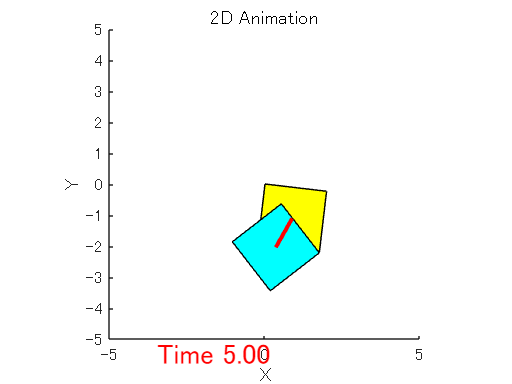




square_size = 1; % 正方形の1辺の長さ
% アニメーションの準備
% figure;
fig = figure;
% set(fig, 'Visible', 'on');
hold on;
axis equal;
axis([-20, 20, -20, 20]/4); % 描画範囲
title('2D Animation');
xlabel('X');
ylabel('Y');

% 初期プロットの設定
square1 = fill([-1, 1, 1, -1]*square_size, [-1, -1, 1, 1]*square_size, 'yellow');
square2 = fill([-1, 1, 1, -1]*square_size, [-1, -1, 1, 1]*square_size, 'cyan');
link_line = plot([0, 0], [0, 0], 'r-', 'LineWidth', 2); % 2つの物体を繋ぐ線
time_text = text(-3.5, -5.5, '', 'FontSize', 14, 'Color', 'red'); % 時間を表示

% アニメーションループ
for t_idx = 1:length(time_steps)
    % 物体1の位置と回転
    x1 = pos(1, t_idx);
    y1 = pos(2, t_idx);
    theta1 = pos(3, t_idx);
    R1 = [cos(theta1), -sin(theta1); sin(theta1), cos(theta1)];
    square1_vertices = R1 * [-1, 1, 1, -1; -1, -1, 1, 1]*square_size + [x1; y1];
    square1.XData = square1_vertices(1, :);
    square1.YData = square1_vertices(2, :);
    
    % 物体2の位置と回転
    x2 = pos(4, t_idx);
    y2 = pos(5, t_idx);
    theta2 = pos(6, t_idx);
    R2 = [cos(theta2), -sin(theta2); sin(theta2), cos(theta2)]; % 回転行列
    square2_vertices = R2 * [-1, 1, 1, -1; -1, -1, 1, 1]*square_size + [x2; y2];
    square2.XData = square2_vertices(1, :);
    square2.YData = square2_vertices(2, :);
    
    % 2つの物体を繋ぐ線
    link_line.XData = [x1, x2];
    link_line.YData = [y1, y2];
    
    % 時間を更新
    time_text.String = sprintf('Time %.2f', time_steps(t_idx));
    
    % 描画を更新
    drawnow;
    
    % 一定時間停止（アニメーションの速度調整）
    pause(0.01);
end